Лабораторная работа №3

Пространственный робот с 3-мя звеньями

Топольницкий А.

Вариант №53

Задание:

- Изучить предоставленные примеры

- Создать структуру робота в соответствии с вариантом

- Реализовать все виды управления и в качестве траектории выбрать любую сложную траекторию:

- Управление на основе ПИД с обратной кинематикой

- Линеаризацию по обратной связи с обратной кинематикой

- Импеданс с компенсацией силы тяжести

- Промоделировать контакт - выполнить мягкое взаимодействие с объектом, расположенным на столе.

Вариант №53, исходные данные:

Три сочленения: первое - вращательное, второе и третье - призматическое;

Вращение происходит вокруг оси Х, линейное перемещение второго звена вдоль Х, третьего - вдоль Z

Исходное положение в случае вращательного соединения = 0 [рад]

Исходное положение в случае призматического соединения = li / 2 [м]

Все звенья имеют квадратное поперечное сечение с указанной шириной

clear; clc;
% to clear the workspace and command window 
% чтобы очистить рабочее пространство и окно команд

format short;
addpath(genpath('mr')); % we use function library by Kevin Lynch / мы используем библиотеку функций Кевина Линча

Variables / Переменные

$q_1, \; q_2, \; q_3  $ are the angles of rotations, $dq_1, \; dq_2, \; dq_3  $ are the angular velocities,  $f_x, \; f_y, \; f_z$ are external load

$q_1, \; q_2, \; q_3  $ являются углами поворота, $dq_1, \; dq_2, \; dq_3  $являются угловыми скоростями,  $f_x, \; f_y, \; f_z$ являются внешней нагрузкой

$l_1,\; l_2, \; l_3$ are lengths, $m_1, \;  m_2, \; m_3 $ are masses, $j_{x_1}, j_{y_1}, j_{z_1}, j_{x_2}, j_{y_2}, j_{z_2}, j_{x_3}, j_{y_3}, j_{z_3} $ are inertias, and $g$ is gravity constant

$l_1,\; l_2, \; l_3$ длины, $m_1, \;  m_2, \; m_3 $ массы, $j_{x_1}, j_{y_1}, j_{z_1}, j_{x_2}, j_{y_2}, j_{z_2}, j_{x_3}, j_{y_3}, j_{z_3} $ инерции, and $g$ гравитационная постоянная

syms q1 q2 q3 dq1 dq2 dq3 fx fy fz
syms l1 l2 l3 m1 m2 m3 jx1 jy1 jz1 jx2 jy2 jz2 jx3 jy3 jz3 g 

Generalized coordinates are the angles of rotations, dq stands for the angular velocities / Обобщенные координаты - это углы поворота, dq обозначает угловые скорости

q = [q1, q2, q3]; 
dq = [dq1, dq2, dq3];

Vectors of unit angular velocities / Векторы единичных угловых скоростей

w1=[-1;0;0]

w1 =     -1
     0
     0


w2=[0;0;0]

w2 =      0
     0
     0


w3=[0;0;0]

w3 =      0
     0
     0


Positon of joints / Расположение сочленений (радиусы векторы до солченений от frame)

r1=[0;0;0]

r1 =      0
     0
     0


r2=[0;0;l1]

$$r2 = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

r3=[l2/2;0;l1]

$$r3 = \left(\begin{array}{c} \frac{l_{2}}{2}\\ 0\\ l_{1} \end{array}\right)$$

Vectors of translation motion / Векторы поступательного движения

v1_unit=-VecToso3(w1)*r1; 
% VecToso3 is a function from mr for skew-symmetric representation
% VecToso3 является функцией из mr для кососимметричного представления
v2_unit=-VecToso3(w2)*r2 + [1;0;0];
v3_unit=-VecToso3(w3)*r3 + [0;0;1];

Unit twists or screws the links / Винтовые оси для звеньев

S1=[w1;v1_unit];
S2=[w2;v2_unit];
S3=[w3;v3_unit];

Home position of CoM and ee / Изначальные положения для центром масс и энд-эффектора

Here by Hc10 I have denoted $H_{c_1}^{0}$. Тут под Hc10 понимается $H_{c_1}^{0}$

Hc10_home=[eye(3,3), [0;0;l1/2];  0,0,0,1]

$$Hc10\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{l_{1}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc20_home=[eye(3,3), [0;0;l1];  0,0,0,1]

$$Hc20\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc30_home=[eye(3,3), [l2/2;0;l1];  0,0,0,1]

$$Hc30\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{l_{2}}{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hee0_home=[eye(3,3), [l2/2;0;l1 + l3/2];  0,0,0,1]

$$Hee0\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{l_{2}}{2}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{1}+\frac{l_{3}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Rotation matrixes / Матрицы поворота


$$R=e^{\tilde{w}}=I+\tilde{w}\sin{\theta}+\tilde{w}^2(1-\cos{\theta})$$


In code by Rij I have denoted $R_i^j$ / В коде под Rij я обозначил$R_i^j$

R10=eye(3,3)+VecToso3(w1)*sin(q1)+VecToso3(w1)^2*(1-cos(q1)) % matrix exponential rodrigues formula

$$R10 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 0 & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) \end{array}\right)$$

R21=eye(3,3)+VecToso3(w2)*sin(q2)+VecToso3(w2)^2*(1-cos(q2)); 
R32=eye(3,3)+VecToso3(w3)*sin(q3)+VecToso3(w3)^2*(1-cos(q3)); 

#### Homogeneous transformation matrixes / Однородная матрица преобразования 

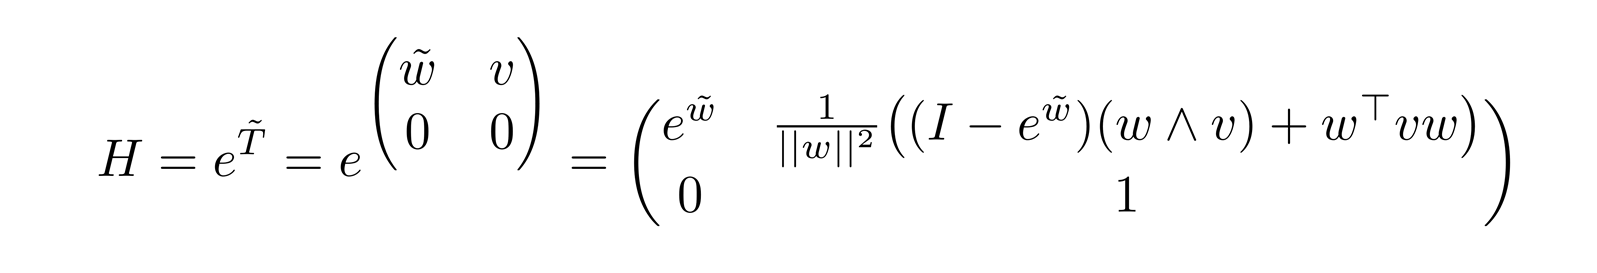

abs_ter_1=(eye(3,3)*q1+(1-cos(q1))*VecToso3(w1)+(q1-sin(q1))*VecToso3(w1)^2)*v1_unit;
abs_ter_2=(eye(3,3)*q2+(1-cos(q2))*VecToso3(w2)+(q2-sin(q2))*VecToso3(w2)^2)*v2_unit;
abs_ter_3=(eye(3,3)*q3+(1-cos(q3))*VecToso3(w3)+(q3-sin(q3))*VecToso3(w3)^2)*v3_unit;

Here by T100 I have denoted $T_1^{0,0}$

e_T100q1=[R10, abs_ter_1; 0,0,0,1];
e_T201q2=[R21, abs_ter_2; 0,0,0,1];
e_T302q3=[R32, abs_ter_3; 0,0,0,1]

$$e\_T302q3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Direct kinematics / Прямая кинематика


$$H_n^0 (q_1, q_2, \dots q_n)=
e^{\tilde{\hat{T}}_1^{0,0}q_1} e^{\tilde{\hat{T}}_2^{0,1}q_2} \dots
e^{\tilde{\hat{T}}_n^{0,(n-1)}q_n} H_n^{0}(0),
$$


Hc10=simplify(e_T100q1*Hc10_home);
Hc20=simplify(e_T100q1*e_T201q2*Hc20_home);
Hc30=simplify(e_T100q1*e_T201q2*e_T302q3*Hc30_home);
Hee0=simplify(e_T100q1*e_T201q2*e_T302q3*Hee0_home);
P=Hee0*[0;0;0;1]

$$P = \left(\begin{array}{c} \frac{l_{2}}{2}+q_{2}\\ \sin\left(q_{1}\right)\,\left(l_{1}+\frac{l_{3}}{2}+q_{3}\right)\\ \cos\left(q_{1}\right)\,\left(l_{1}+\frac{l_{3}}{2}+q_{3}\right)\\ 1 \end{array}\right)$$


Hc01=TransInv(Hc10);
Hc02=TransInv(Hc20);
Hc03=TransInv(Hc30)

$$Hc03 = \left(\begin{array}{cccc} 1 & 0 & 0 & -\frac{l_{2}}{2}-q_{2}\\ 0 & \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ 0 & \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \left(-l_{1}-q_{3}\right)\,{\cos\left(q_{1}\right)}^{2}+\left(-l_{1}-q_{3}\right)\,{\sin\left(q_{1}\right)}^{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H0ee=TransInv(Hee0)

$$H0ee = \left(\begin{array}{cccc} 1 & 0 & 0 & -\frac{l_{2}}{2}-q_{2}\\ 0 & \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ 0 & \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \left(-l_{1}-\frac{l_{3}}{2}-q_{3}\right)\,{\cos\left(q_{1}\right)}^{2}+\left(-l_{1}-\frac{l_{3}}{2}-q_{3}\right)\,{\sin\left(q_{1}\right)}^{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

TransInv is a function from mr to take an inverse of H / TransInv - это функция от mr чтобы брать обратную от  H

#### Geometriacal Jacobians / Геометрические матрицы якоби

J1=S1;
J2=simplify(Adjoint(e_T100q1*e_T201q2)*S2);
J3=simplify(Adjoint(e_T100q1*e_T201q2*e_T302q3)*S3);
J_1=[J1, zeros(6,1), zeros(6,1)];
J_2=[J1, J2, zeros(6,1)];
J_3=[J1, J2, J3]

$$J\_3 = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & \sin\left(q_{1}\right)\\ 0 & 0 & \cos\left(q_{1}\right) \end{array}\right)$$

Coordinates of CoM / z координаты центров масс

zc1=[0, 0, 1, 0]*Hc10*[0;0;0;1];
zc2=[0, 0, 1, 0]*Hc20*[0;0;0;1];
zc3=[0, 0, 1, 0]*Hc30*[0;0;0;1]

$$zc3 = \cos\left(q_{1}\right)\,\left(l_{1}+q_{3}\right)$$

Inertia / инерция

j1=[jx1, 0, 0; 0, jy1, 0; 0, 0, jz1];
j2=[jx2, 0, 0; 0, jy2, 0; 0, 0, jz2];
j3=[jx3, 0, 0; 0, jy3, 0; 0, 0, jz3];
I1=[j1, zeros(3,3); zeros(3,3), eye(3,3)*m1];
I2=[j2, zeros(3,3); zeros(3,3), eye(3,3)*m2];
I3=[j3, zeros(3,3); zeros(3,3), eye(3,3)*m3]

$$I3 = \left(\begin{array}{cccccc} {\mathrm{jx}}_{3} & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{jy}}_{3} & 0 & 0 & 0 & 0\\ 0 & 0 & {\mathrm{jz}}_{3} & 0 & 0 & 0\\ 0 & 0 & 0 & m_{3} & 0 & 0\\ 0 & 0 & 0 & 0 & m_{3} & 0\\ 0 & 0 & 0 & 0 & 0 & m_{3} \end{array}\right)$$

#### Mass matrix and other terms of dynamic equation / Матрица массы и другие члены динамического уравнения

M_1 = simplify(J_1.'*Adjoint(Hc01).'*I1*Adjoint(Hc01)*J_1);
M_2 = simplify(J_2.'*Adjoint(Hc02).'*I2*Adjoint(Hc02)*J_2);
M_3 = simplify(J_3.'*Adjoint(Hc03).'*I3*Adjoint(Hc03)*J_3);
M = M_1+M_2+M_3

$$M = \left(\begin{array}{ccc} {\mathrm{jx}}_{1}+{\mathrm{jx}}_{2}+{\mathrm{jx}}_{3}+\frac{{l_{1}}^{2}\,m_{1}}{4}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+m_{3}\,{q_{3}}^{2}+2\,l_{1}\,m_{3}\,q_{3} & 0 & 0\\ 0 & m_{2}+m_{3} & 0\\ 0 & 0 & m_{3} \end{array}\right)$$


V = simplify(m1*g*zc1+m2*g*zc2+m3*g*zc3);
N = simplify([diff(V,q1); diff(V,q2); diff(V,q3)])

$$N = \left(\begin{array}{c} -\frac{g\,\sin\left(q_{1}\right)\,\left(l_{1}\,m_{1}+2\,l_{1}\,m_{2}+2\,l_{1}\,m_{3}+2\,m_{3}\,q_{3}\right)}{2}\\ 0\\ g\,m_{3}\,\cos\left(q_{1}\right) \end{array}\right)$$

C = simplify(getC(M, q ,dq))

$$C = \left(\begin{array}{c} -{\mathrm{dq}}_{1}\,m_{3}\,\left(l_{1}+q_{3}\right)\\ 0\\ 0 \end{array}\right)$$

Wrench / Пространственный ко-вектор внешней нагрузки

W = [0, 0, 0, fx, fy, fz]

$$W = \left(\begin{array}{cccccc} 0 & 0 & 0 & \mathrm{fx} & \mathrm{fy} & \mathrm{fz} \end{array}\right)$$

Joints' torque / Момент на сочленениях

tau = simplify(J_3.'*Adjoint(H0ee).'*W.')

$$tau = \left(\begin{array}{c} \mathrm{fy}\,\left(l_{1}+\frac{l_{3}}{2}+q_{3}\right)\\ \mathrm{fx}\\ \mathrm{fz} \end{array}\right)$$

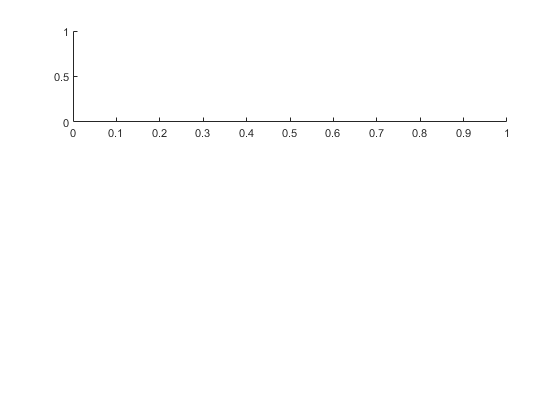


clear all
% масса звеньев в килограммах 
m1 = 6.287;
m2 = 17.506;
m3 = 6.494; 

% длины звеньев в метрах
l1 = 0.45;
l2 = 0.22;
l3 = 0.28;

% ширина звеньев в метрах
w1 = 0.135;
w2 = 0.066;
w3 = 0.084;
AB = [w1/2 w1/2 l1];
BC = [l2 w2/2 w2/2];
CD = [w3/2 w3/2 l3];
Base = [0.3*l1 0.3*l1 0.3*l1];
figure;
subplot(3,1,1);

plot(out.qs.q1_des.time, out.qs.q1_des.Data)

Unable to resolve the name out.qs.q1_des.time.

hold on
plot(out.qs.q1_act.time,out.qs.q1_act.Data, 'LineStyle','--')
grid minor;
legend('$q1_{des}$', '$q1_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Angle$ [rad]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение обобщённой координаты q1')
subplot(3,1,2);
plot(out.qs.q2_des.time, out.qs.q2_des.Data)
hold on
plot(out.qs.q2_act.time,out.qs.q2_act.Data,'LineStyle','--')
grid minor;
legend('$q2_{des}$', '$q2_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Angle$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение обобщённой координаты q2')
subplot(3,1,3);
plot(out.qs.q3_des.time, out.qs.q3_des.Data)
hold on
plot(out.qs.q3_act.time,out.qs.q3_act.Data,'LineStyle','--')
grid minor;
legend('$q3_{des}$', '$q3_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Angle$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение обобщённой координаты q3')
figure;
subplot(3,1,1)
hold on
plot(out.pos.p_des.time, out.pos.p_des.data(:,1))
plot(out.pos.p_act.time, out.pos.p_act.data(:,1),'LineStyle','--')
grid minor
legend('$x_{des}$', '$x_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$X$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение координаты Х')
subplot(3,1,2)
hold on
plot(out.pos.p_des.time, out.pos.p_des.data(:,2))
plot(out.pos.p_act.time, out.pos.p_act.data(:,2),'LineStyle','--')
grid minor
legend('$y_{des}$', '$y_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Y$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение координаты Y')
subplot(3,1,3)
hold on
plot(out.pos.p_des.time, out.pos.p_des.data(:,3))
plot(out.pos.p_act.time, out.pos.p_act.data(:,3),'LineStyle','--')
grid minor
legend('$z_{des}$', '$z_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$Z$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Сравнение координаты Z')
figure;
plot3(out.pos.p_des.data(:,1),out.pos.p_des.data(:,2),out.pos.p_des.data(:,3))
hold on
plot3(out.pos.p_act.data(:,1),out.pos.p_act.data(:,2),out.pos.p_act.data(:,3), 'LineStyle','--')
legend('$p_{des}$', '$p_{act}$',  'fontsize',14,'interpreter','latex')
xlabel('$x$ [m]', 'fontsize',14,'interpreter','latex');
ylabel('$y$ [m]', 'fontsize',14,'interpreter','latex');
zlabel('$z$ [m]', 'fontsize',14,'interpreter','latex');
grid minor


figure;
plot(out.tau.tau1.time,out.tau.tau1.data)
grid minor
legend('$tau1$','fontsize',14,'interpreter','latex');
ylabel('$M$ [N * m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Момент 1 звена')
ylim([-50, 50])
figure;
hold on 
plot(out.tau.tau2.time,out.tau.tau2.data)
plot(out.tau.tau3.time,out.tau.tau3.data)
grid minor
legend('$tau2$', '$tau3$',  'fontsize',14,'interpreter','latex');
ylabel('$F$ [N]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
title('Момент 2 и 3 звена')
ylim([-50, 50])



function [C] = getC(M, q, dq)

    n = size(M, 1);
    G = sym(zeros(n, n, n)); % cristofil symbol G_ijk
   
    for i = 1:n
        for j = 1:n
            for k = 1:n
                G(i, j, k) =  sym(1/2) * (diff(M(i, j), q(k)) + diff(M(i, k), q(j)) - diff(M(k, j), q(i)));
            end
        end
    end

    C = sym(zeros(n, 1)); % coriolis and centrifugal C = \sum c_{ijk} \dot{q}_i
         for j = 1:n
            sum = 0;
            for k = 1:n
                sum = sum + G(i, j, k) * dq(k);
         end
    C(j) = sum;
    end
end